# Réplica híbrida Simulink–MATLAB del espectro de Lyapunov por promedio de autovalores (Lara et al., 2003)

Réplica computacional del artículo «Estimación de los exponentes de Lyapunov» (Lara, Stoico, Machado y Castagnino, ENIEF 2003) sobre el sistema de Lorenz. Implementación: carpeta lara-lyapunov-2003 (Simulink + MATLAB R2024a).

## 1. Introducción

Los exponentes de Lyapunov cuantifican la dependencia sensible a las condiciones iniciales: miden la tasa media de separación exponencial de trayectorias vecinas. En un sistema disipativo tridimensional, la firma de un atractor extraño es un espectro de signos (+, 0, −): expansión en una dirección, neutralidad a lo largo del flujo y contracción fuerte en la tercera. El sistema de Lorenz es el paradigma clásico de este comportamiento.

Lara y colaboradores proponen un espectro alternativo de coeficientes Λk: congelar la matriz jacobiana en cada ventana de integración, diagonalizar localmente el sistema variacional y promediar la parte real de los autovalores sobre la órbita. El método aspira a la misma descripción asintótica que el espectro de Lyapunov — coincidencia de signos y de clase de atractor — con menor tiempo de cómputo y mayor simplicidad de cálculo.

El método de referencia es el de Benettin con reortonormalización de Gram–Schmidt: se integra la órbita junto con su base tangente — doce estados en Lorenz — y en cada ventana dT se factoriza V = QR para acumular log(diag(R)) / dT. Es el patrón oro del cálculo de espectros, pero paga álgebra matricial repetida y exige renormalización periódica para evitar el desbordamiento.

Estos experimentos replican el artículo con diseño híbrido: el modelo Simulink lorenz_sim.slx aporta la órbita y MATLAB promedia los autovalores; se barre r de 20 a 30 con tf = 10000; se cronometra el método frente a Gram–Schmidt en dimensión 2 a 20; y se contrasta un subconjunto con la implementación Benettin preexistente.

## 2. Materiales y métodos

### 2.1. Modelo de Lorenz y obtención de la órbita

El modelo lorenz_sim.slx implementa el sistema con tres integradores (condiciones x0, y0, z0), ganancias sigma y beta, productos cruzados y registros To Workspace xsim, ysim, zsim. Se fija sigma = 10, beta = 8/3, rho = r y condición (0, 1, 0), con resolutor ode4 de paso fijo 0.001. El envoltorio runSimulinkTrajectory asigna parámetros con assignin y StopTime con set_param, silencia la StopFcn durante el barrido y restaura modelo y workspace al terminar.


$$\frac{dx}{dt} = \sigma (y - x), \frac{dy}{dt} = x (r - z) - y, \frac{dz}{dt} = x y - b z$$


### 2.2. Espectro por promedio de autovalores

La ecuación variacional usa J sobre la órbita; en cada ventana se congela Ji = J(ti) y sus autovalores dan las tasas locales: solo la parte real estira o encoge, la imaginaria rota. El estimador es la media de Re lambda con historial acumulado para el régimen cuasi-estacionario, ordenado de mayor a menor. Lectura por signos: todo negativo, punto fijo; un positivo con divergencia negativa, extraño; divergencia positiva, inestabilidad fuerte.


$$\delta \dot{y}_{k} = \lambda_{ik} \delta y_{k}, \frac{\delta y_{k,i+1}}{\delta y_{k,i}} = \exp(\lambda_{ik} \epsilon)$$



$$\Lambda^{n}_{k} = \frac{1}{n} \sum_{i=1}^{n} \mathrm{Re}(\lambda_{ik}), \Lambda_{k} = \lim_{n \to \infty} \Lambda^{n}_{k}$$



$$\sum_{k} \Lambda_{k} = \mathrm{div} f = -(\sigma + 1 + b) = -13.667$$


### 2.3. Barrido, contraste y benchmark

El barrido recorre r = 20 a 30 con tf = 10000 y stride = 100 — unas 100 000 ventanas por valor —, exige cierre en −13.667 con tolerancia 0.05 y clasifica cada régimen. El contraste usa la función Benettin sin modificar (Tben = 500, ode45, dT = 0.5, 25 por ciento de transitorio) en r = 23, 24, 25 y 28. El benchmark cronometra ambos estimadores en osciladores lineales con nIter = 2000 y dt = 0.5 (mediana de tres repeticiones).

res = runLorenzSweep('RhoRange', 20:30, 'Horizon', 10000, 'Stride', 100, 'GsSubset', [23 24 25 28]);

## 3. Resultados

El barrido reproduce la transición: para r = 20 a 24 todo es negativo — punto fijo — con Lambda_1 de −0.15445 a −0.02191; en r = 25 salta a +1.60958 con el resto en −0.71081 y −14.56544: extraño. En r = 28 da +1.64191 y en r = 30 +1.65738. La suma cierra en −13.66667 exacta en las once corridas. Lambda_1 en r = 20 y r = 24 coincide con el Gram–Schmidt del artículo hasta la tercera cifra.

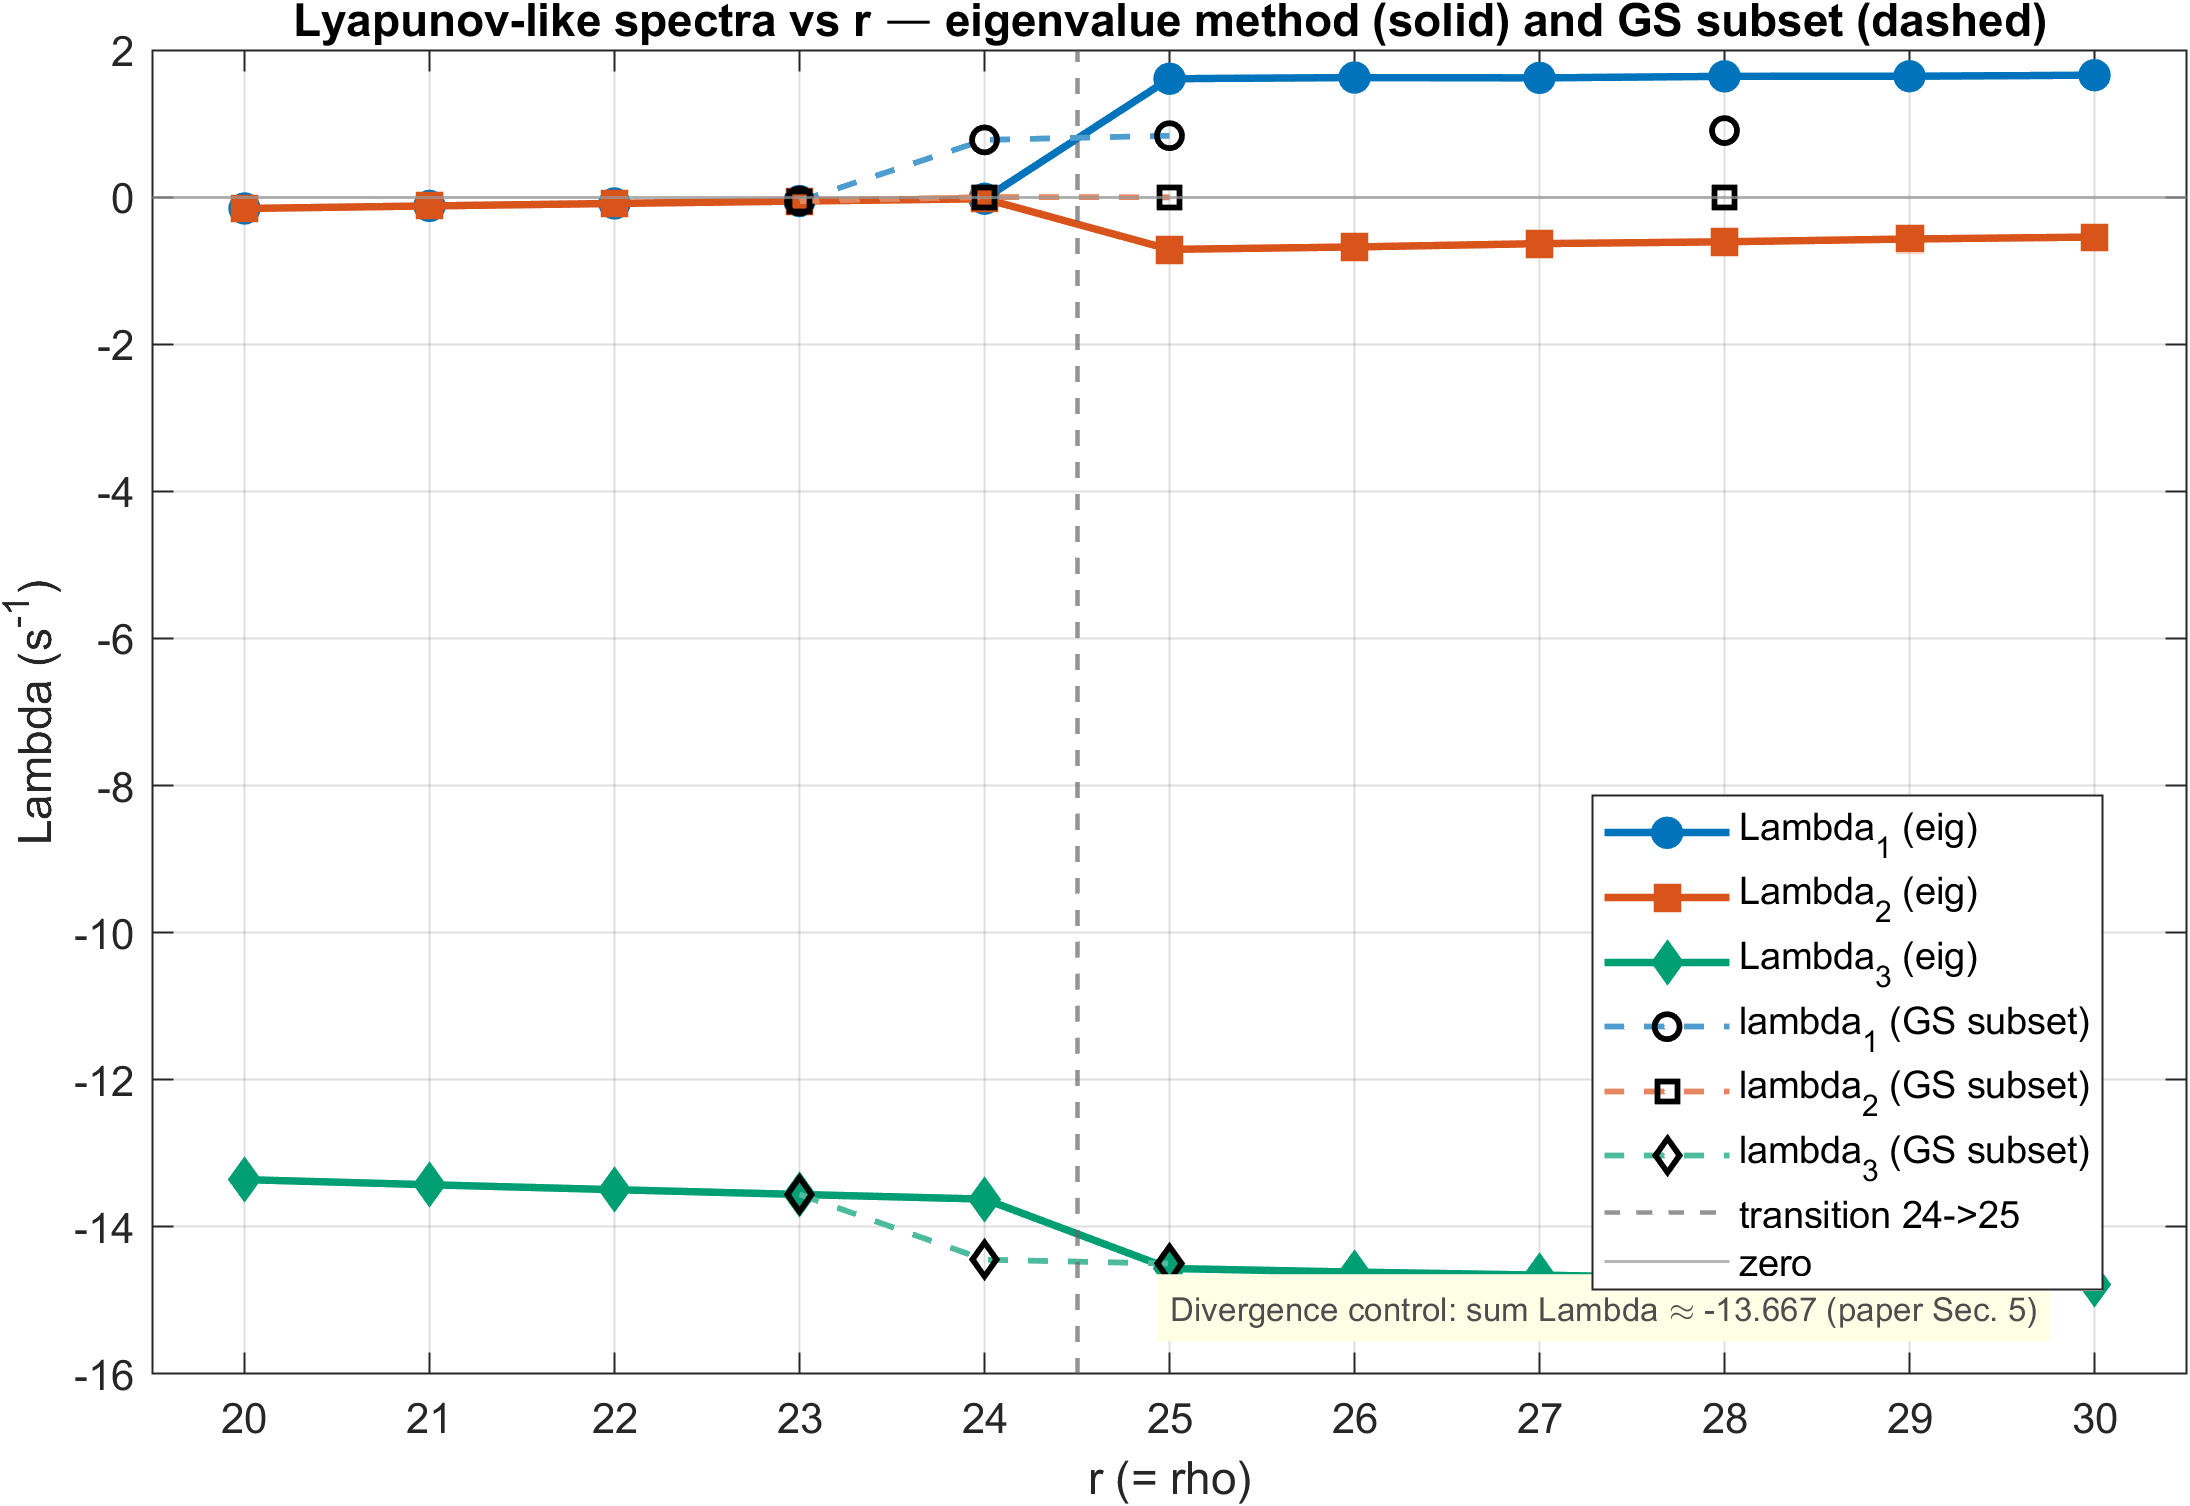

Figura 1. Espectros Lambda(r) por autovalores (continuo) con subconjunto Gram–Schmidt (discontinuo). La vertical marca la transición 24 → 25.

El contraste confirma la equivalencia salvo un caso instructivo: en r = 23 el Gram–Schmidt corto da [−0.0535, −0.0545, −13.5588], en r = 25 lambda_1 = 0.8349 y en r = 28 lambda_1 = 0.9041, coherentes con el artículo; pero en r = 24 devuelve +0.778 frente a −0.0219. Junto a la bifurcación opera la relentización crítica y el horizonte corto queda dominado por el transitorio: el horizonte largo es imprescindible allí.

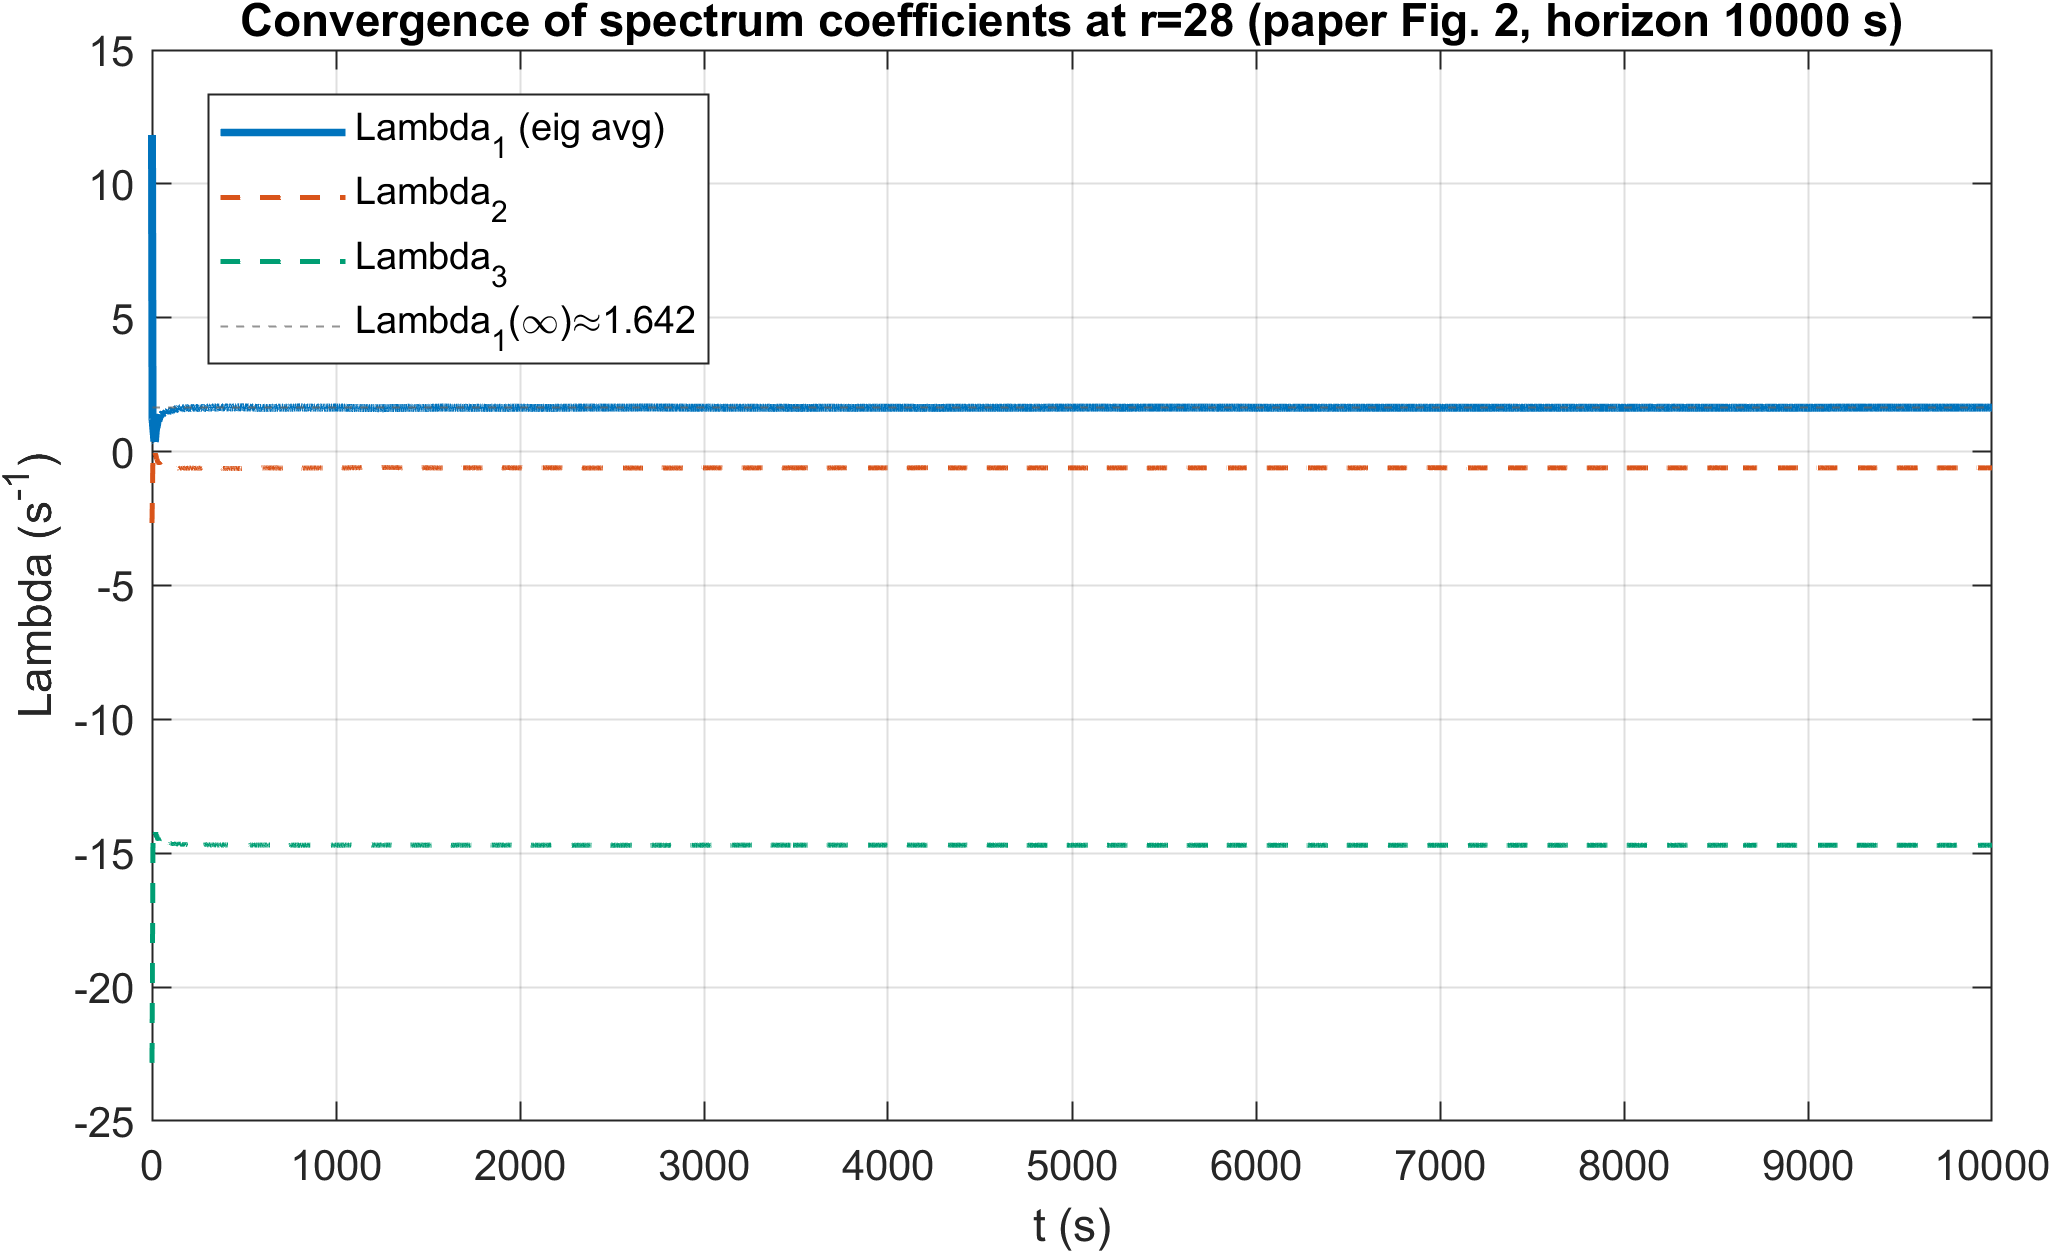

Figura 2. Convergencia de Lambda_1(t) en r = 28 hacia el valor cuasi-estacionario.

El benchmark muestra al método de autovalores más rápido en toda la dimensión 2 a 20, con speedups de 2.81 en m = 2, 6.15 en m = 6 y 4.55 en m = 20: la tendencia creciente de la Tabla 1, aunque los segundos absolutos dependen de la máquina.

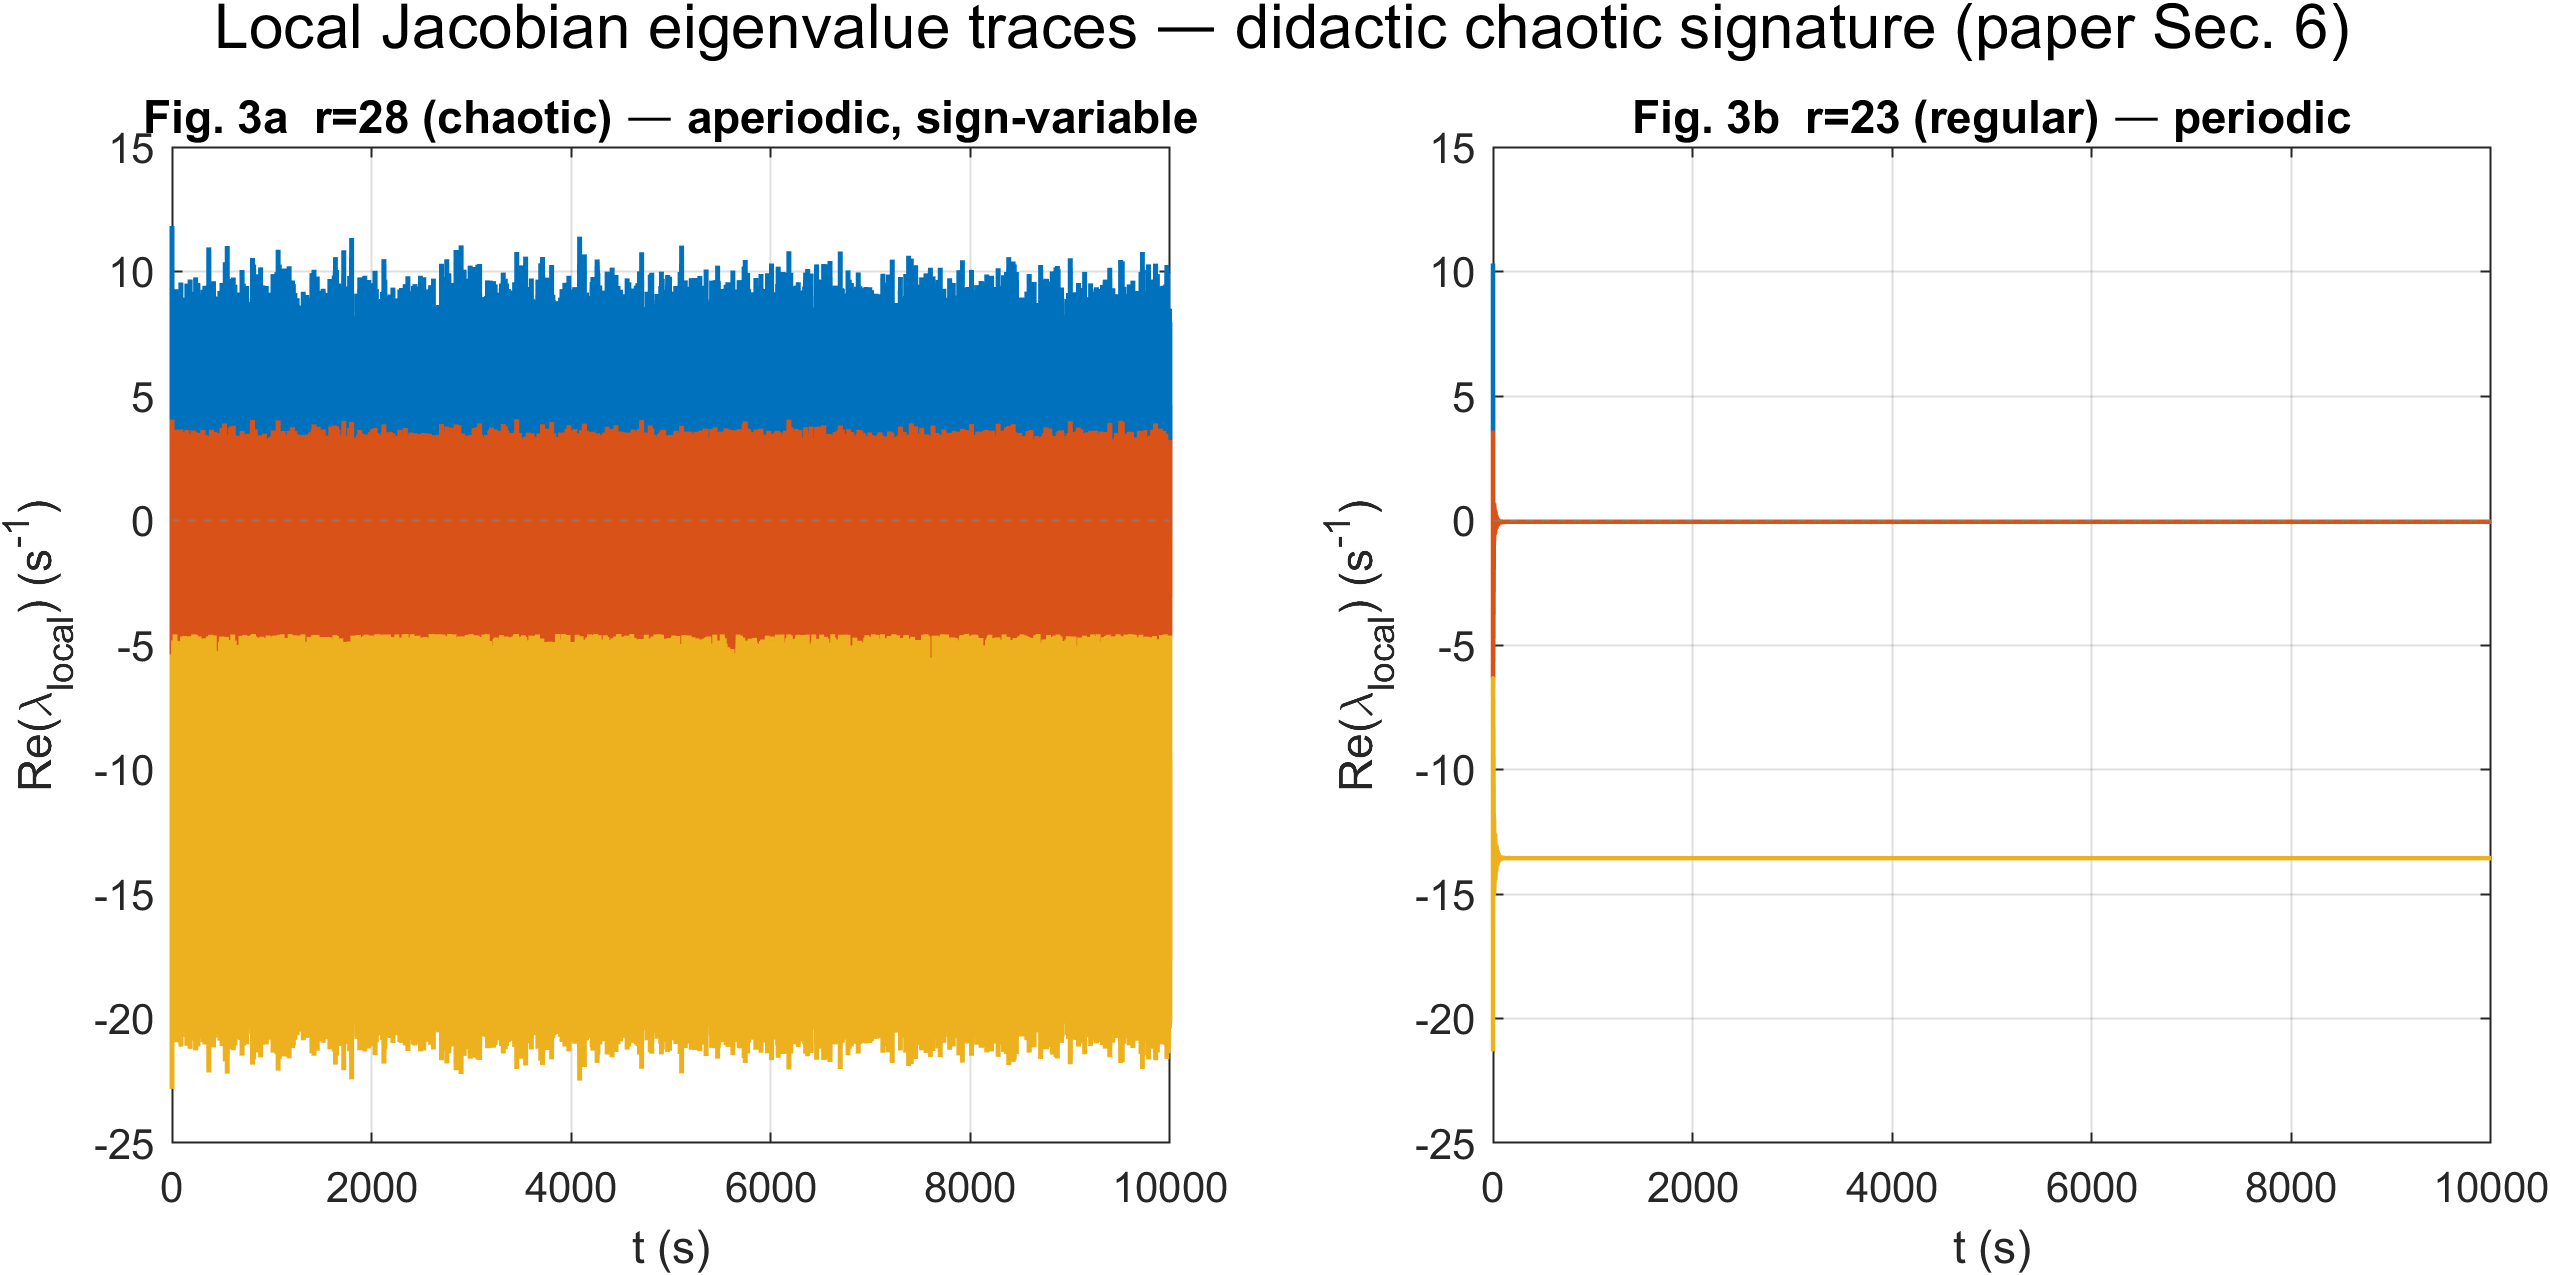

Figura 3. Trazas de Re(lambda local): r = 28 aperiódica con cambios de signo (a); r = 23 periódica (b).

Las trazas exhiben la firma didáctica del caos: en régimen caótico algún autovalor oscila aperiódicamente cambiando de signo — la órbita alterna irregularmente estabilidad e inestabilidad — mientras que en régimen regular el registro es periódico.

## 4. Conclusiones

La réplica confirma la tesis del artículo: el promedio de autovalores da la misma descripción asintótica con menor coste, la transición 24 → 25 queda reproducida y la divergencia cierra exacta. El desacuerdo en r = 24 con horizonte corto refuerza la metodología: cerca de la bifurcación solo el horizonte largo decide. Limitaciones: paso fijo frente al variable del artículo, contraste en subconjunto y benchmark sin Simulink. Futuro: archivar el barrido completo, extender el contraste y empaquetar el núcleo como librería.

## Referencias

[1] Lara, Stoico, Machado y Castagnino, «Estimación de los exponentes de Lyapunov», Mecánica Computacional Vol. XXII, ENIEF 2003.

[2] Benettin, Galgani, Giorgilli y Strelcyn, «Lyapunov characteristic exponents for smooth dynamical systems and for Hamiltonian systems», Meccanica 15, 9–20, 1980.

[3] Lorenz, «Deterministic nonperiodic flow», J. Atmos. Sci. 20, 130–141, 1963.

[4] Strogatz, Nonlinear Dynamics and Chaos, Addison-Wesley, 1994.

[5] Parker y Chua, Practical Numerical Algorithms for Chaotic Systems, Springer, 1989.

[6] Ramasubramanian y Sriram, «A comparative study of computation of Lyapunov spectra with different algorithms», Physica D 139, 72–86, 2000.

[7] Sprott, «Simple chaotic systems and circuits», Am. J. Phys. 68 (8), 2000.

[8] The MathWorks, documentación de Simulink: resolvedor ode4 de paso fijo, 2024.